# Exemple pentru metoda secantei

## Prezentarea metodei

Dorim să rezolvăm ecuația $f(x)=0$. 

Metoda: se pornește cu două valori $x_0$ și $x_1$ date și se execută pasul iterativ


$$x_{k+1}=x_k-\frac{x_k-x_{k-1}}{f\left( x_k \right)-f\left( x_{k-1} \right)}f\left( x_k \right)$$


până când $\vert x_{k+1}- x_k \vert<\varepsilon$, $\varepsilon$ precizie dată.

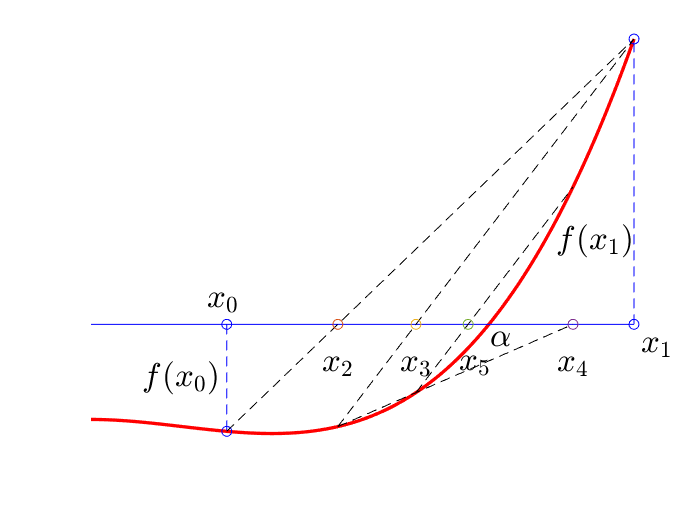

Dăm o implementare pentru metoda secantei

## Exemplu: o ecuație algebrică

Utilizați metoda secantei pentru a determina rădăcinile polinomului $p(x)=4x^3-16x^2+17x-4$. 

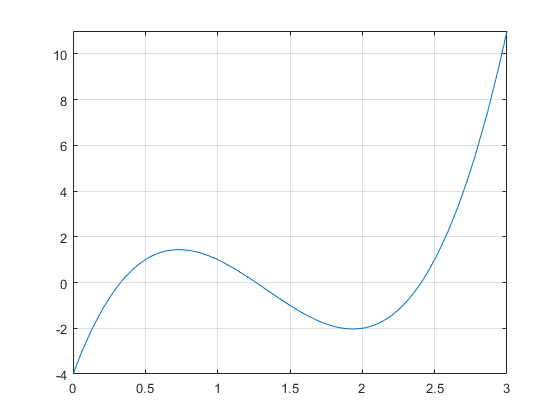

f=@(x) 4*x.^3-16*x.^2+17*x-4;
fplot(f,[0,3])
grid on

Vom determina rădăcinile dând valori de pornire diferite.

format long
x0=0; x1=0.5;
[z1,ni1]=secant(f,x0,x1,1e-8)

xn =    0.400000000000000


xn =    0.301587301587301


xn =    0.331689496702842


xn =    0.328666321887440


xn =    0.328537831849161


xn =    0.328538458735604


xn =    0.328538458611415


z1 =    0.328538458611415


ni1 =      7


x0=1; x1=1.5;
[z2,ni2]=secant(f,x0,x1,1e-8)

xn =    1.250000000000000


xn =    1.264705882352941


xn =    1.264658145668493


xn =    1.264658290063096


xn =    1.264658290064420


z2 =    1.264658290064420


ni2 =      5


x0=2; x1=2.5;
[z3,ni3]=secant(f,x0,x1,1e-8)

xn =    2.333333333333333


xn =    2.397727272727273


xn =    2.407793018725779


xn =    2.406790959938006


xn =    2.406803234835744


xn =    2.406803251324440


xn =    2.406803251324166


z3 =    2.406803251324166


ni3 =      7


Verificare

f([z1,z2,z3])

ans = 	1.0e+-14 *

   0.177635683940025   0.355271367880050   0.710542735760100


## Exemplu, convergență rapidă

Rezolvăm ecuația $f(x)=3e^x-4\cos x=0$, cu valorile de pornire $x_0=0.9,\ x_1=1$.

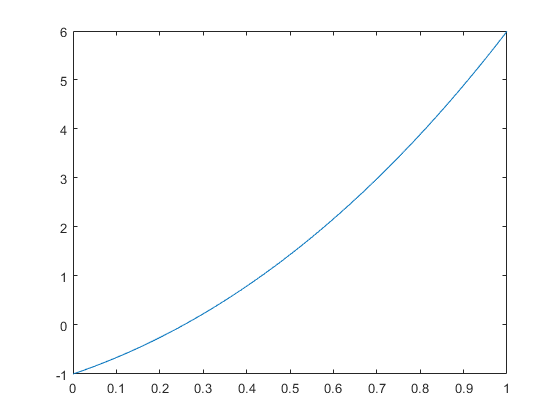

f=@(x) 3*exp(x)-4*cos(x);
fplot(f,[0,1])

x0=0.9; x1=1;
[z,ni]=secant(f,x0,x1,1e-8)

xn =    0.455750754163146


xn =    0.327871769957798


xn =    0.264686861190796


xn =    0.255389916278810


xn =    0.254854242870341


xn =    0.254850060820066


xn =    0.254850059028856


z =    0.254850059028856


ni =      7


f(z)

ans =      2.842170943040401e-14


## Exemplu, convergența lentă

Rezolvăm ecuația $f(x)=1-10x+25x^2=0$, cu valorile de pornire $x_0=0.9,\ x_1=1$.

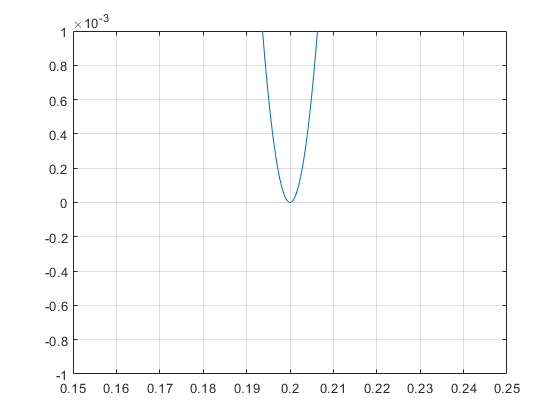

f=@(x) 1-10*x+25*x.^2;
fplot(f,[0.15,0.25])
ylim([-0.001,0.001])
grid on

x0=0.9; x1=1;
[z,ni]=secant(f,x0,x1,1e-8)

xn =    0.573333333333333


xn =    0.454545454545455


xn =    0.351351351351351


xn =    0.294915254237288


xn =    0.258333333333333


xn =    0.236129032258065


xn =    0.222310756972112


xn =    0.213793103448276


xn =    0.208523592085236


xn =    0.205268109125118


xn =    0.203255813953487


xn =    0.202012217031978


xn =    0.201243615367532


xn =    0.200768597309908


xn =    0.200475019085587


xn =    0.200293577981662


xn =    0.200181441161240


xn =    0.200112136806885


xn =    0.200069304357547


xn =    0.200042832448623


xn =    0.200026471908962


xn =    0.200016360539570


xn =    0.200010111369423


xn =    0.200006249169611


xn =    0.200003862198632


xn =    0.200002386969911


xn =    0.200001475225829


xn =    0.200000911740906


xn =    0.200000563486565


xn =    0.200000348256905


xn =    0.200000215220366


xn =    0.200000133053521


xn =    0.200000082212626


xn =    0.200000050808469


xn =    0.200000031364619


xn =    0.200000019547914


xn =    0.200000011670111


z =    0.200000011670111


ni =     37


f(z)

ans =      3.330669073875470e-15


Rădăcina este dublă

## Exemplu, convergență oscilantă

Rezolvăm ecuația $f(x)=\arctan x=0$, cu valorile de pornire $x_0=1.35,\ x_1=1.30$.

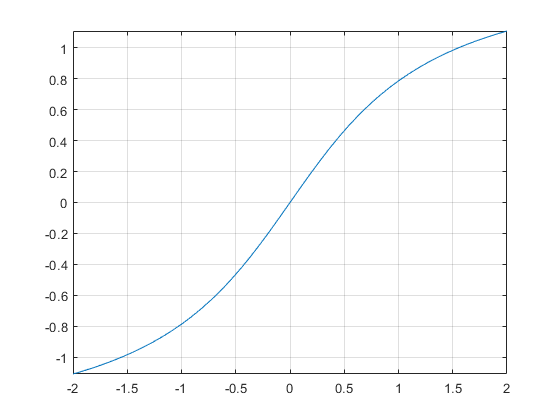

fplot(@atan,[-2,2])
grid on

x0=1.35; x1=1.30;
[z,ni]=secant(@atan,x0,x1,1e-8)

xn =   -1.221379205686021


xn =    0.018036298196726


xn =   -0.006723294978555


xn =      4.572205813098765e-07


xn =     -6.888649339108900e-12


xn =      4.798293787661118e-25


z =      4.798293787661118e-25


ni =      6


atan(z)

ans =      4.798293787661118e-25


Cu alte valori de pornire

x0=-0.5; x1=0.5;
[z,ni]=secant(@atan,x0,x1,1e-8)

xn =      0


xn =      0


z =      0


ni =      2


## Exemplu, divergență spre infinit

Rezolvăm ecuația $f(x)=xe^{-x}=0$, cu valorile de pornire $x_0=1.5,\ x_1=2$.

f=@(x) x.*exp(-x)

f = function_handle with value:
    @(x)x.*exp(-x)


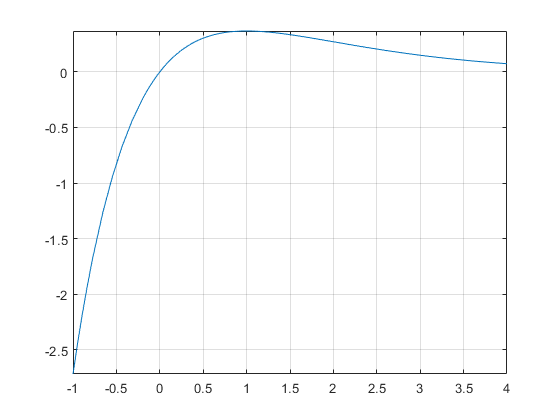

fplot(f,[-1,4]); grid on

x0=1.5; x1=2;
try
[z,ni]=secant(f,x0,x1,1e-8,0,10)
catch
    disp('divergenta');
end

xn =    4.113798873326397


xn =    4.812506336752700


xn =    5.784065580728313


xn =    6.594867561790274


xn =    7.428064134749158


xn =    8.227217596978685


xn =    9.020294500885157


xn =    9.800986646316584


xn =   10.574639777228054


xn =   11.341330397463748


divergenta


## Secantă în complex

Se pot determina rădăcinile complexe dând valori de pornire complexe și făcând calcule în complex.

f=@(x) x.^3-x-1;
x0=1i; x1=1+i;
[z,ni]=secant(f,x0,x1,1e-8)

xn =   0.166666666666667 + 0.500000000000000i


xn =   0.133234859675037 + 0.064106351550960i


xn =  -0.745209084703168 - 0.174130537387710i


xn =  -1.638240444887840 - 0.709799445528432i


xn =  -0.639069389172700 - 0.263385924849088i


xn =  -0.567329256233182 - 0.353102165665599i


xn =  -0.677730453827664 - 0.696173478536001i


xn =  -0.655951074477077 - 0.525937407436081i


xn =  -0.663015300836206 - 0.557144246188224i


xn =  -0.662276037135116 - 0.562485170389563i


xn =  -0.662360022940334 - 0.562278749138417i


xn =  -0.662358978938995 - 0.562279512120051i


xn =  -0.662358978622373 - 0.562279512062301i


z =  -0.662358978622373 - 0.562279512062301i


ni =     13


f(z)

ans =     -1.110223024625157e-15
